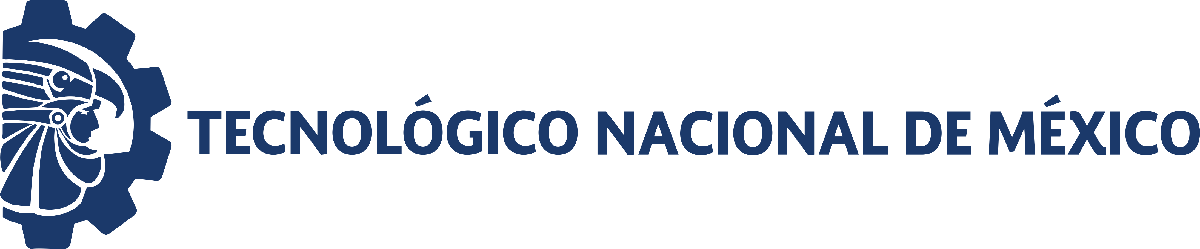                                 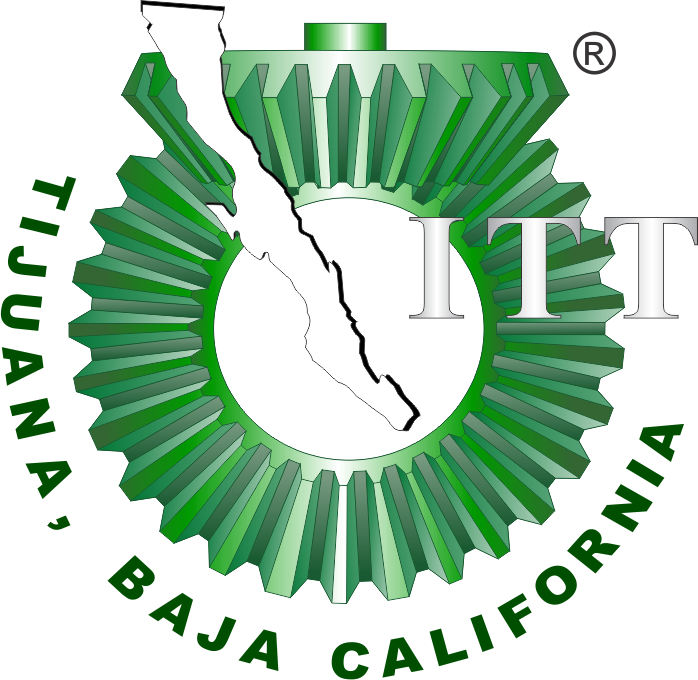

# **Proyecto: Sistema Inmunológico**

# **Patología: Virus del SIDA (VIH)**

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

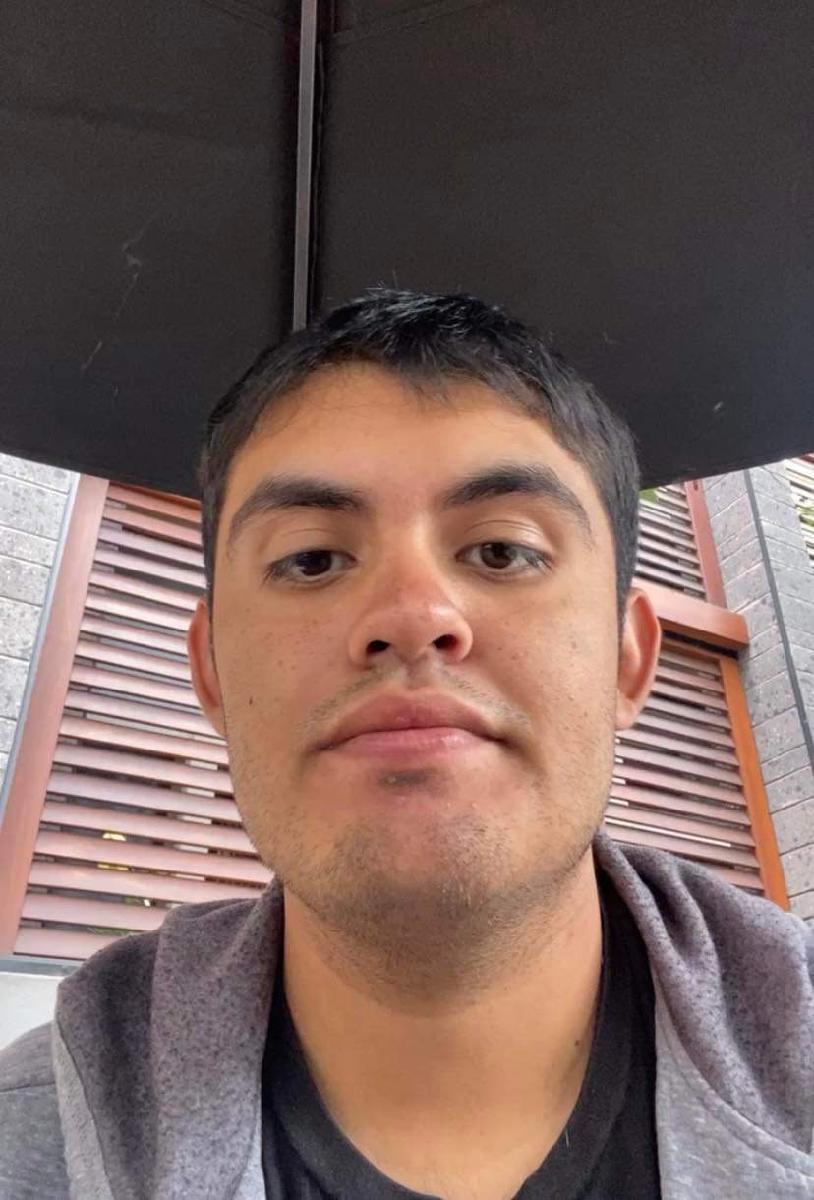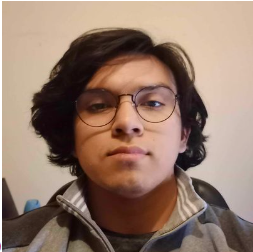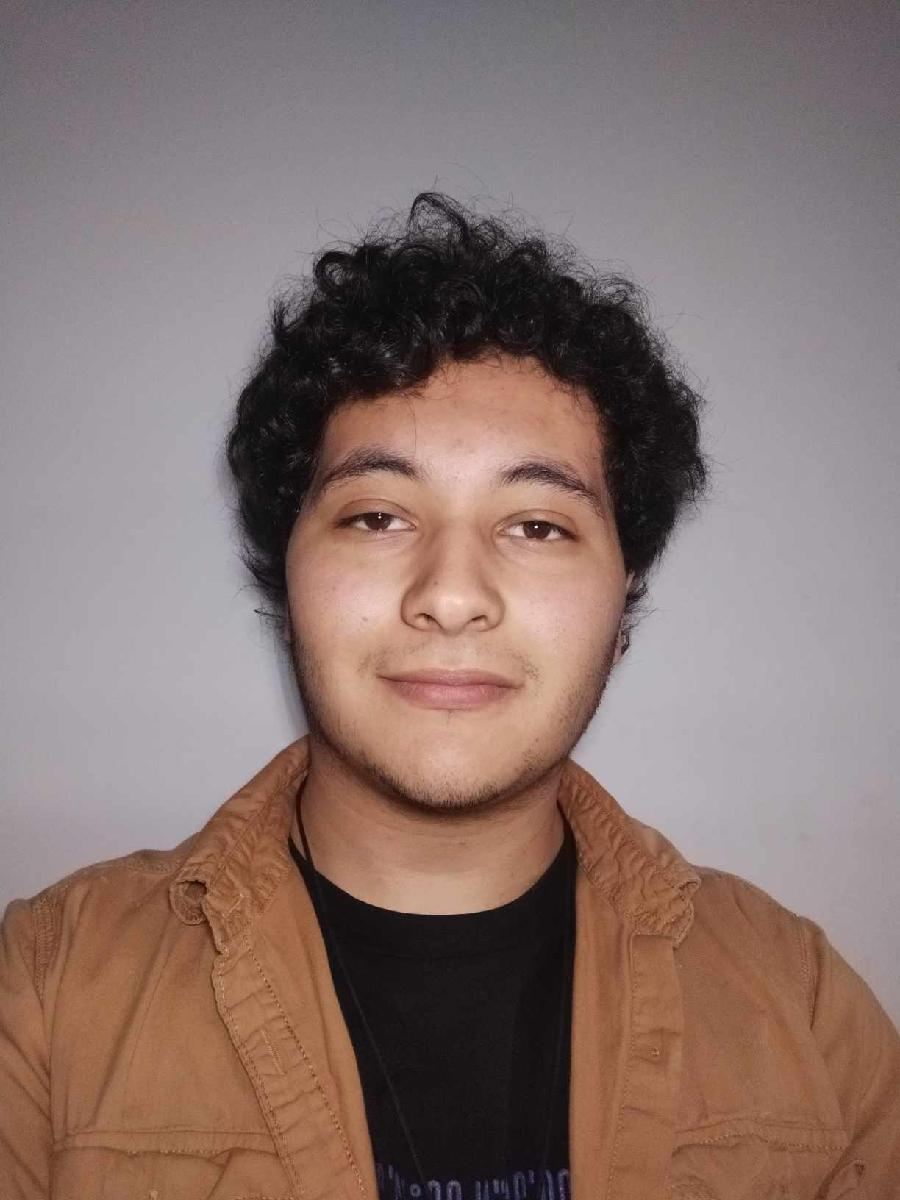

Nombre del alumno: **Andres Martin Bañuelos Elas; Alain Yahir Chaparro Zamora;** **Héctor Ándres Fernández Esquivel**

Número de control: **21212142; 21212147; 21212153**

Correo institucional:**l21212142@tectijuana.edu.mx; l21212147@tectijuana.edu.mx;** **l21212153@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

kP = 67.6355

kI = 47202.5937

kD = 0.015336

Rise time = 7.7e-05 s

Setting time = 0.000718 s

Overshoot = 48 %

Peak = 1.48 V

clc; clear; close all; warning('off','all')
tend = '0.1';
file = 'Sistema';
open_system(file);
parameters.StopTime = tend;
parameters.Solver = 'ode1';
parameters.MaxStep = '1E-6';

## Respuesta del sistema

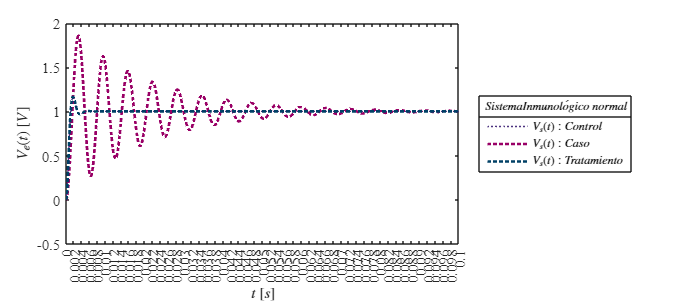

set_param('Sistema/PID Controller','P','67.6355');
set_param('Sistema/PID Controller','I','47202.5937');
set_param('Sistema/PID Controller','D','0.015336');
Signal = 'Respuesta de sistema inmunologico';
N = sim(file,parameters);
plotsignals(N.t,N.Vsx,N.Vsy,N.Vsz,Signal)

## Función: Respuesta a la señal

function plotsignals(t,Vsx,Vsy,Vsz,Signal)
    set(figure(),'Color','w')
    set(gcf,'units','centimeters','position',[1,1,18,8])
    set(gca,'FontName','Times New Roman', 'FontSize',11)
    hold on; grid off; box on

    plot(t,Vsx,':','LineWidth',1,'Color',[0.3,0.2,0.5])
    plot(t,Vsy,':','LineWidth',2,'Color',[0.6,0,0.4])
    plot(t,Vsz,':','LineWidth',2,'Color',[0,0.25,0.4])

    L = legend('$V_s(t):Control$','$V_s(t):Caso$','$V_s(t):Tratamiento$');
    set(L,'Interpreter','Latex','FontSize',9,'Location','EastOutside','Box','On')

    xlabel('$t$ $[s]$','Interpreter','Latex','FontSize',11)
    ylabel('$V_e(t)$ $[V]$','Interpreter','Latex','FontSize',11)
   
    title(L,"$Sistema Inmunol\acute{o}gico$ $normal$")
    figname = 'Respuesta del sistema Inmunologico';
    xlim([0,0.1]); xticks(0:0.002:0.1)
    ylim([-0.5,2]); yticks(-0.5:0.5:2)
    exportgraphics(gcf,[Signal,'.pdf'],'ContentType','vector')
end